# `Script to Plot Multiple Datasets on One Plot`

Read in JSON File for plotting configuration, specify base path

clf
clear

david_file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\";
kristen_file_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\";

base_path = kristen_file_path;

json_text = fileread(base_path + "config_files/" + "test_config.json");
sim_config = jsondecode(json_text);
json_text_plot = fileread(base_path + "config_files/" + "plot_config.json");
plot_config = jsondecode(json_text_plot);

Specify desired title

desired_title = "P(detection) for 1GHz at Various Target Ranges";

Automatically set up JSON configurations

plot_p_detection = plot_config.PlotSettings.Configurations.plot_p_detection;
plot_p_false_pos = plot_config.PlotSettings.Configurations.plot_p_false_pos;
NUM_RUNS = plot_config.PlotSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = plot_config.PlotSettings.Configurations.max_bin;
BIN_WIDTH = plot_config.PlotSettings.Configurations.bin_width;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Specify CSVs to 

csvs = ["1GHz_no_attack.csv", "100MHz_no_attack.csv"];
% csvs = ["4GHz_no_attack.csv", "4GHz_sim_slope_noisy_vel.csv",...
%     "4GHz_target.csv","4GHz_sim_slope_sim_vel.csv"];
% csvs = ["20MHz_sim_slope_noisy_vel.csv", "100MHz_sim_slope_noisy_vel.csv",...
%     "1GHz_sim_slope_noisy_vel.csv","4GHz_sim_slope_noisy_vel.csv"];

colors_list = ["b", "g", "c", "m", "y", "k", "r"];
color_idx = 1;

for csv = csvs
    table_data = readtable(base_path + "csvs_to_plot/" + csv);
    range_col = table_data{:, 1};
    bin_classification = cast(range_col/BIN_WIDTH, "int16")';
    histogram_vals = zeros(MAX_BIN,3);
    bin_counts = zeros(MAX_BIN, 4);

    for bin_num = 1:MAX_BIN
        histogram_vals(bin_num, 1) = bin_num;
        count = 0;
        detected = 0;
        false_pos = 0;
        for frame = 1: TOTAL_FRAMES
            if (bin_classification(frame) == bin_num)
                count = count + 1;
                if table_data{frame, 3}
                    detected = detected + 1;
                end
                if table_data{frame, 8}
                    false_pos = false_pos + 1;
                end
            end
        end
        bin_counts(bin_num, 1) = bin_num;
        bin_counts(bin_num, 2) = detected;
        bin_counts(bin_num, 3) = false_pos;
        bin_counts(bin_num, 4) = count;

        if (count ~= 0)
            histogram_vals(bin_num, 2) = detected/count;
            histogram_vals(bin_num, 3) = false_pos/count;
        end
    end

    if (plot_p_detection)
        hold on
        plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,2), colors_list(color_idx),'Marker', 'o', 'MarkerFaceColor', colors_list(color_idx), 'MarkerSize', 4 );
        color_idx = color_idx +1;
        hold off
    end

    if (plot_p_false_pos)
        hold on
        plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,3), colors_list(color_idx));
        color_idx = color_idx + 1;
        hold off
    end
    bin_counts_filename = csv.replace(".csv", "") + "_bin_counts" + ".csv";
    bin_counts_table = array2table(bin_counts, "VariableNames", ["Bin #", "Detected Count", "False Pos. Count", "Totals"])
    writetable(bin_counts_table,bin_counts_filename,'WriteRowNames',true); 
end

bin_counts_table = 30×4 table
    Bin #    Detected Count    False Pos. Count    Totals
    _____    ______________    ________________    ______

      1            13                 0              13  
      2            55                 1              55  
      3            42                 0              42  
      4            44                 0              44  
      5            15                 0              15  
      6            38                 0              38  
      7            24                 1              24  
      8            31                 1              31  
      9            40                 0              40  
     10            21                 0              21  
     11            12                 0              12  
     12            41                 0              41  
     13            38

bin_counts_table = 30×4 table
    Bin #    Detected Count    False Pos. Count    Totals
    _____    ______________    ________________    ______

      1             0                 0              17  
      2             0                 0              55  
      3             3                 3              23  
      4            31                 9              40  
      5            36                 1              37  
      6            28                 0              28  
      7            26                 4              30  
      8            50                 1              53  
      9            62                 4              69  
     10            37                 1              38  
     11            46                 1              47  
     12            45                 3              50  
     13            23

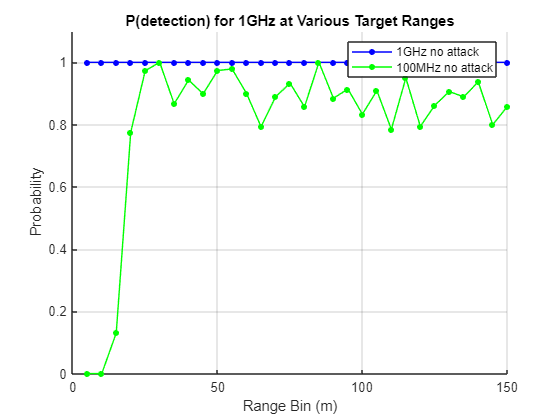


ylabel("Probability")
ylim([0,1.1])
legend(csvs.replace("_", " ").replace(".csv", ""))
xlabel("Range Bin (m)")
title(desired_title)
grid()

%print('-r300',"generated_plots/combined_result_plot",'-dsvg')
%print('-r300',"generated_plots/combined_result_plot",'-dpng')